# Active filters

Main advantages

- Provide isolation (cascade filters)

- Can have a sharper roll-off

- Boosts the power

- Can have a DC gain greater than unity

An active device (such as an op amp) is a device that requires its own power supply. It therefore uses more power than a passive circuit, but as a result, it amplifies the input and can be used to create a higher order filter (sharper roll off).  It also provides isolation so that filters can be cascaded.

obs: $\omega=2\pi f$

## Example

### Analog Anti-Aliasing Filter (*Copyright 2016-2019 The MathWorks, Inc.)*

This example shows an analog implementation of an anti-aliasing filter for use with an A-to-D converter. The filter cut-off frequency is set to 500Hz in order to match the A-to-D converter sampling frequency of 1kHz. The test signal incorporates a desired 50Hz sinusoid plus a higher frequency component at 1100Hz that cannot be captured with a 1kHz A-to-D sampling frequency. The scope shows the captured signal without and with anti-aliasing. With the anti-alias filter the 50Hz sine wave amplitude is correctly measured with an amplitude of 1 and corresponding power of 0.5W, i.e., 27dBm for a 1ohm reference load.

#### Model

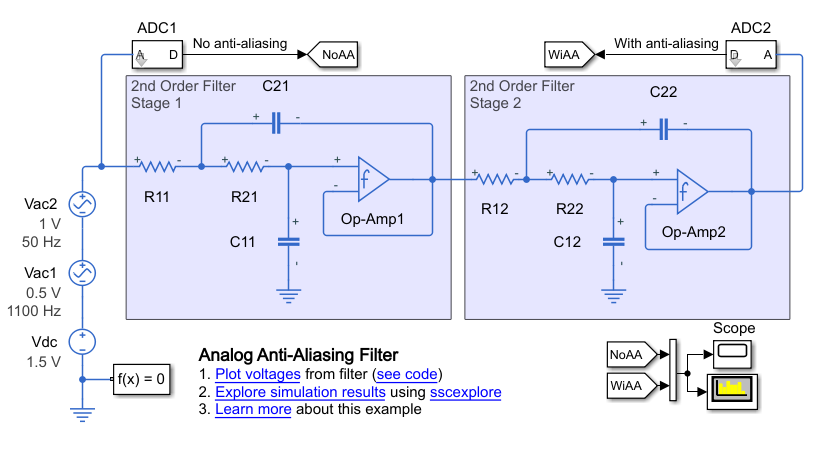

**Simulation Results from Simscape Logging**

The plot below shows the input and output voltages of the anti-aliasing filter.

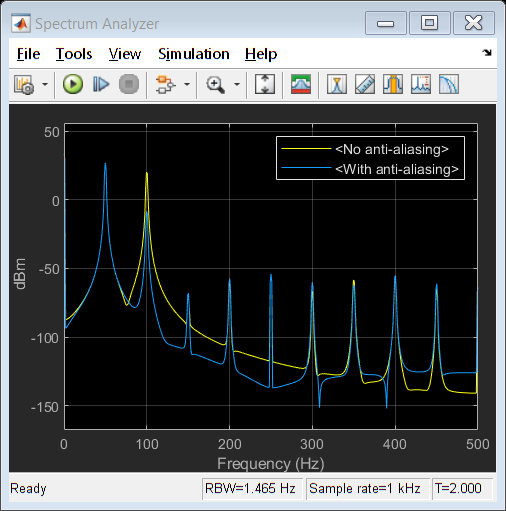

% Generate new simulation results if they don't exist or if they need to be updated
if ~exist('simlog_ee_a2d_sd_anti_alias', 'var') || ...
        simlogNeedsUpdate(simlog_ee_a2d_sd_anti_alias, 'ee_a2d_sd_anti_alias') 
    sim('ee_a2d_sd_anti_alias')
    % Model StopFcn callback adds a timestamp to the Simscape simulation data log
end

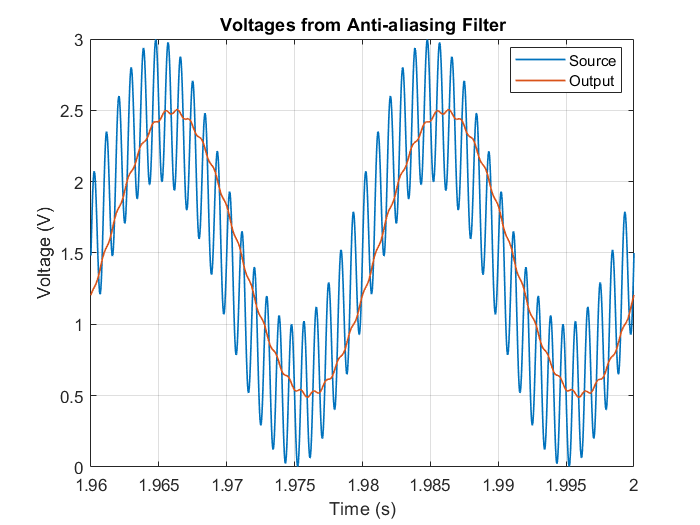


% Reuse figure if it exists, else create new figure
if ~exist('h1_ee_a2d_sd_anti_alias', 'var') || ...
        ~isgraphics(h1_ee_a2d_sd_anti_alias, 'figure')
    h1_ee_a2d_sd_anti_alias = figure('Name', 'ee_a2d_sd_anti_alias');
end
figure(h1_ee_a2d_sd_anti_alias)
clf(h1_ee_a2d_sd_anti_alias)

% Get simulation results
simlog_t = simlog_ee_a2d_sd_anti_alias.Vac2.p.v.series.time;
simlog_Vin = simlog_ee_a2d_sd_anti_alias.Vac2.p.v.series.values('V');
simlog_Vo = simlog_ee_a2d_sd_anti_alias.Op_Amp2.out.v.series.values('V');

% Plot results
plot(simlog_t, simlog_Vin, 'LineWidth', 1)
hold on
plot(simlog_t, simlog_Vo, 'LineWidth', 1)
hold off
grid on
title('Voltages from Anti-aliasing Filter')
ylabel('Voltage (V)')
legend({'Source','Output'},'Location','Best');

set(gca,'XLim',[simlog_t(end)-0.04 simlog_t(end)]);

xlabel('Time (s)')


% Remove temporary variables
clear simlog_t simlog_handles
clear simlog_Vin simlog_Vo